filePath = fullfile('..','data', '24-02-15-16-46-40-112_5_500Nm__200_rpm.tdms')

filePath = '..\data\24-02-15-16-46-40-112_5_500Nm__200_rpm.tdms'

convertedPath = fullfile('.', 'converted_data', '24-02-15-16-46-40-112_5_500Nm__200_rpm.tdms')

convertedPath = '.\converted_data\24-02-15-16-46-40-112_5_500Nm__200_rpm.tdms'

data = tdmsread(convertedPath)

data = 1×1 cell array
    {4500000×6 table}


% Load the TDMS data table from the 1x1 cell array
dataTable = data{1};

% Display the first few rows of the table to confirm its structure
disp('First few rows of the table:');

First few rows of the table:


disp(head(dataTable));

                Time                 Dev1/ai0     Dev1/ai1     Dev1/ai2      Dev1/ai3     Dev1/ai4 
    _____________________________    _________    _________    _________    __________    _________

    2024-02-15 16:46:40.633938399    0.0073242    0.0036621    0.0073242    -0.0024414    0.0024414
    2024-02-15 16:46:40.633948399    0.0073242    0.0036621    0.0061035    -0.0012207    0.0036621
    2024-02-15 16:46:40.633958399    0.0085449    0.0048828    0.0073242    -0.0036621    0.0048828
    2024-02-15 16:46:40.633968399    0.0061035    0.0048828    0.0048828    -0.0024414    0.0036621
    2024-02-15 16:46:40.633978399    0.0048828    0.0073242    0.0048828    -0.0036621    0.0024414
    2024-02-15 16:46:40.633988399    0.0061035    0.0036621    0.0073242    -0.0012207    0.002


% Convert the Time column to a datetime array
dataTable.Time = datetime(dataTable.Time, 'InputFormat', 'yyyy-MM-dd HH:mm:ss.SSSSSSSSS');

% Define the sensitivity of the accelerometer (in mV/g)
sensitivity = 1.02;

% Convert voltage to acceleration in g
for i = 2:width(dataTable)
    dataTable{:, i} = dataTable{:, i} / sensitivity;
end

disp(head(dataTable))

                Time                 Dev1/ai0     Dev1/ai1     Dev1/ai2      Dev1/ai3     Dev1/ai4 
    _____________________________    _________    _________    _________    __________    _________

    2024-02-15 16:46:40.633938399    0.0071806    0.0035903    0.0071806    -0.0023935    0.0023935
    2024-02-15 16:46:40.633948399    0.0071806    0.0035903    0.0059838    -0.0011968    0.0035903
    2024-02-15 16:46:40.633958399    0.0083774    0.0047871    0.0071806    -0.0035903    0.0047871
    2024-02-15 16:46:40.633968399    0.0059838    0.0047871    0.0047871    -0.0023935    0.0035903
    2024-02-15 16:46:40.633978399    0.0047871    0.0071806    0.0047871    -0.0035903    0.0023935
    2024-02-15 16:46:40.633988399    0.0059838    0.0035903    0.0071806    -0.0011968    0.002


% Initialize arrays to store statistics
numChannels = width(dataTable) - 1;
means = zeros(1, numChannels);
rmsValues = zeros(1, numChannels);
variances = zeros(1, numChannels);
peakToPeaks = zeros(1, numChannels);
kurtoses = zeros(1, numChannels);
skewnesses = zeros(1, numChannels);


% Calculate statistics for each channel
for i = 2:width(dataTable)
    channelData = dataTable{:, i};
    means(i-1) = mean(channelData);
    rmsValues(i-1) = rms(channelData);
    variances(i-1) = var(channelData);
    peakToPeaks(i-1) = peak2peak(channelData);
    kurtoses(i-1) = kurtosis(channelData);
    skewnesses(i-1) = skewness(channelData);
end


% Display statistics
for i = 2:width(dataTable)
    channelName = dataTable.Properties.VariableNames{i};
    fprintf('Statistics for %s:\n', channelName);
    fprintf('  Mean: %f g\n', means(i-1));
    fprintf('  RMS: %f g\n', rmsValues(i-1));
    fprintf('  Variance: %f (g^2)\n', variances(i-1));
    fprintf('  Peak-to-Peak: %f g\n', peakToPeaks(i-1));
    fprintf('  Kurtosis: %f\n', kurtoses(i-1));
    fprintf('  Skewness: %f\n', skewnesses(i-1));
end

Statistics for Dev1/ai0:


  Mean: 0.002953 g


  RMS: 0.008740 g


  Variance: 0.000068 (g^2)


  Peak-to-Peak: 0.305176 g


  Kurtosis: 4.828284


  Skewness: 0.035134


Statistics for Dev1/ai1:


  Mean: 0.002706 g


  RMS: 0.009010 g


  Variance: 0.000074 (g^2)


  Peak-to-Peak: 0.309963 g


  Kurtosis: 7.345830


  Skewness: 0.358140


Statistics for Dev1/ai2:


  Mean: 1.571975 g


  RMS: 3.751248 g


  Variance: 11.600756 (g^2)


  Peak-to-Peak: 9.194767 g


  Kurtosis: 3.912294


  Skewness: 1.706481


Statistics for Dev1/ai3:


  Mean: -0.001979 g


  RMS: 0.003389 g


  Variance: 0.000008 (g^2)


  Peak-to-Peak: 0.319537 g


  Kurtosis: 413.882061


  Skewness: -0.261232


Statistics for Dev1/ai4:


  Mean: 0.002387 g


  RMS: 0.003797 g


  Variance: 0.000009 (g^2)


  Peak-to-Peak: 0.348259 g


  Kurtosis: 437.185962


  Skewness: -0.298211


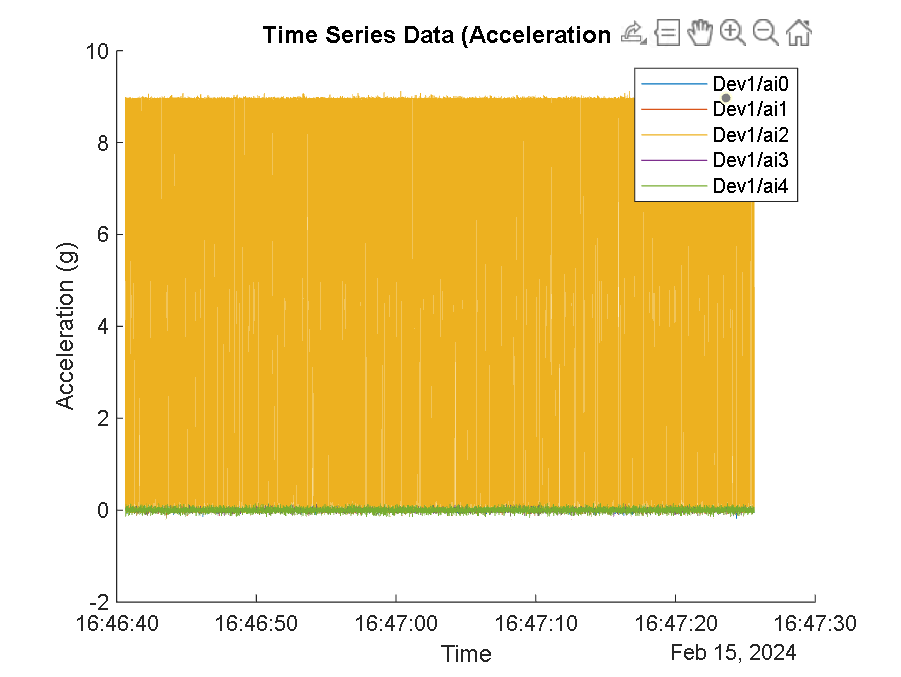


% Plot the data for each channel
figure;
hold on; % Allows multiple plots on the same figure

% Plot each channel against time
for i = 2:width(dataTable)
    plot(dataTable.Time, dataTable{:, i}, 'DisplayName', dataTable.Properties.VariableNames{i});
end

% Add title and labels
title('Time Series Data (Acceleration in g)');
xlabel('Time');
ylabel('Acceleration (g)');

% Add a legend
legend show;

% Display the figure
hold off;

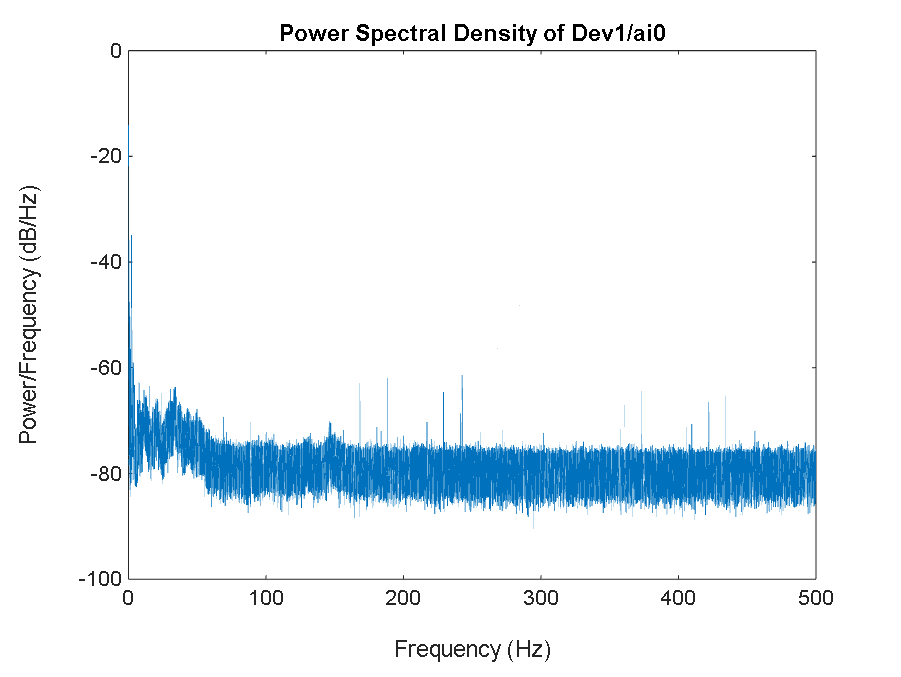

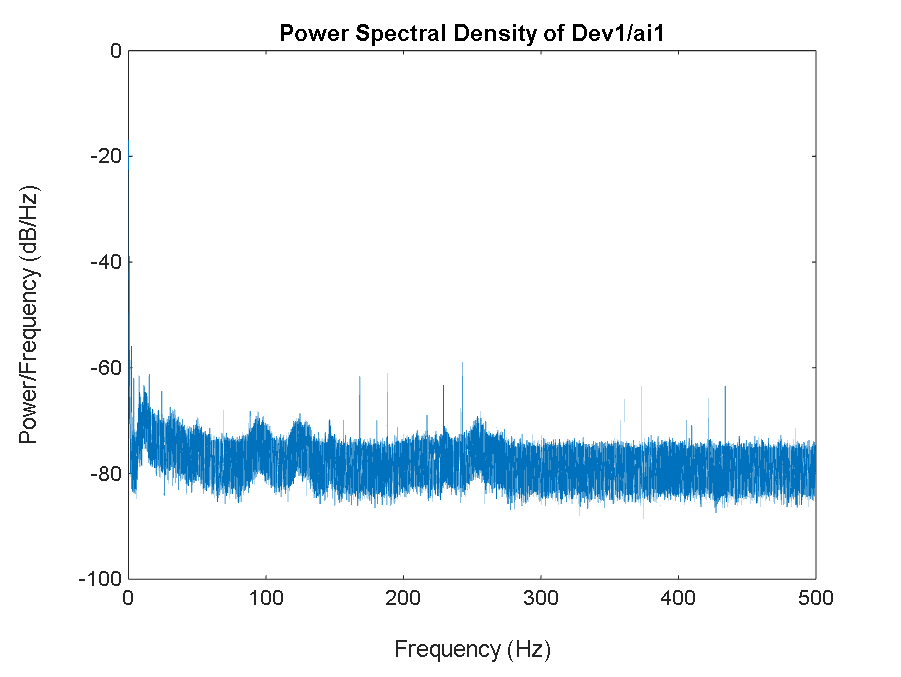

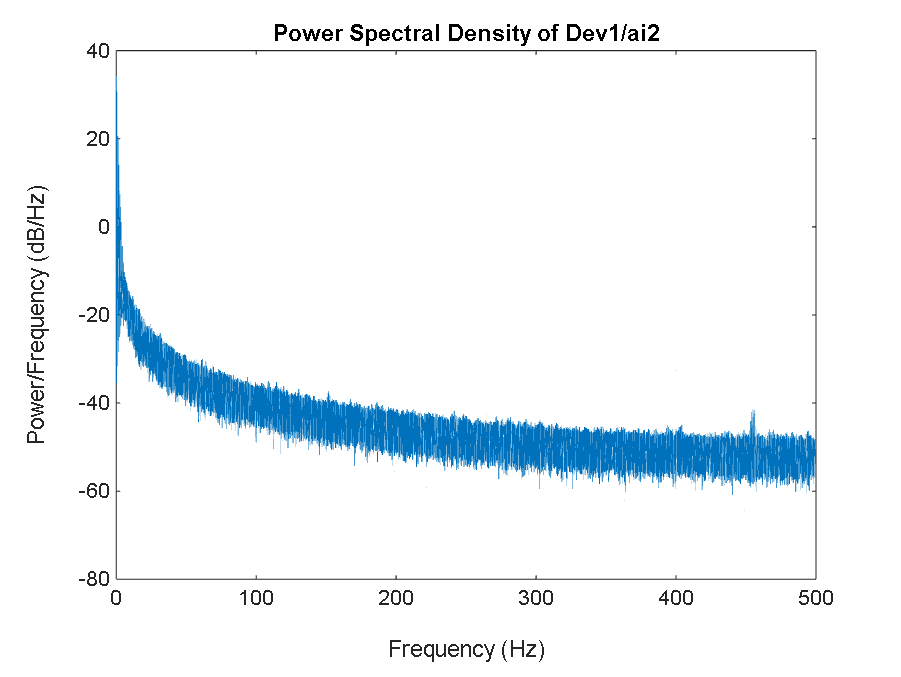

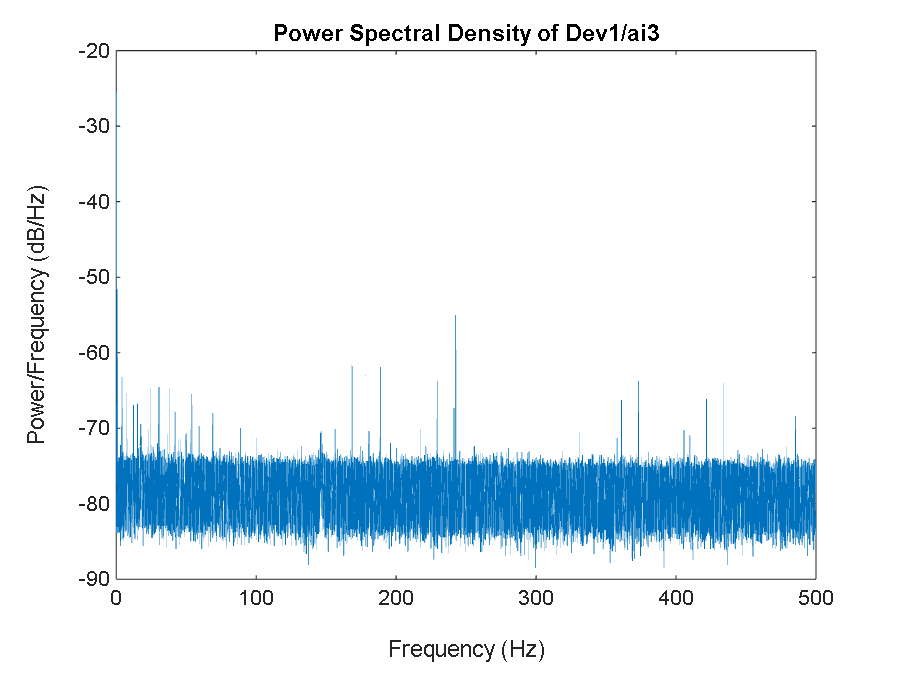

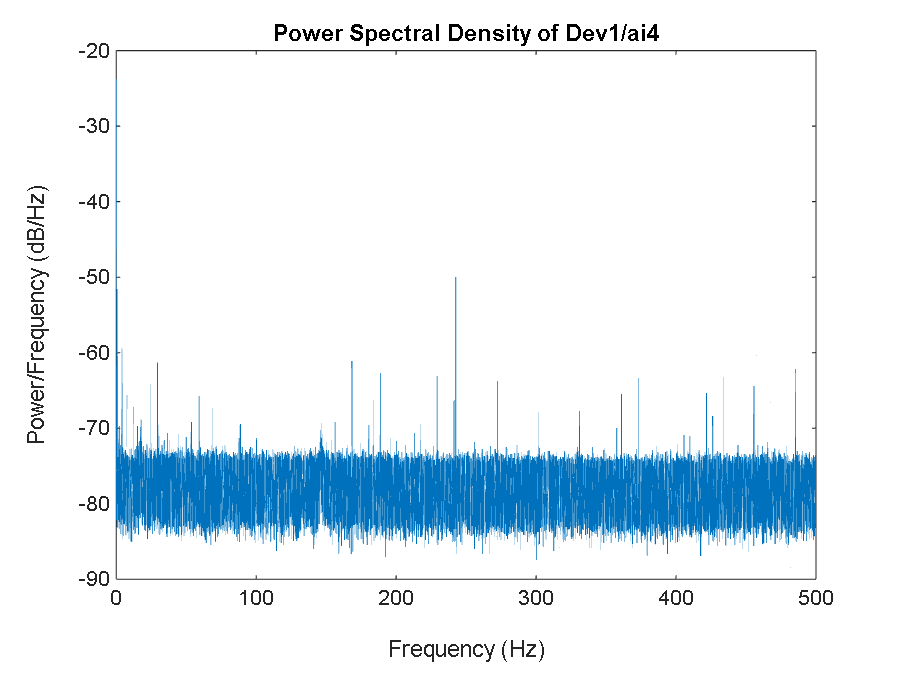


% Frequency domain analysis parameters
Fs = 1000; % Sampling frequency (Hz), adjust this value based on your data
N = length(dataTable.Time); % Number of samples
T = 1 / Fs; % Sampling period

% Initialize arrays to store frequency domain features
peakFrequencies = zeros(1, numChannels);
bandPowers = zeros(1, numChannels);
spectralCentroids = zeros(1, numChannels);

% Frequency domain analysis for each channel
for i = 2:width(dataTable)
    channelData = dataTable{:, i};
    
    % Compute the Fourier Transform
    Y = fft(channelData);
    P2 = abs(Y / N);
    P1 = P2(1:N/2+1);
    P1(2:end-1) = 2 * P1(2:end-1);
    
    % Frequency vector
    f = Fs * (0:(N/2)) / N;
    
    % Estimate the Power Spectral Density (PSD) using Welch's method
    [pxx, f_psd] = pwelch(channelData, [], [], [], Fs);
    
    % Find peak frequencies
    [~, locs] = findpeaks(pxx, 'SortStr', 'descend');
    peakFrequencies(i-1) = f_psd(locs(1));
    
    % Compute band power (e.g., in the band 0-50 Hz)
    band = (f_psd >= 0 & f_psd <= 50);
    bandPowers(i-1) = bandpower(pxx, f_psd, 'psd', band);
    
    % Compute spectral centroid
    spectralCentroids(i-1) = sum(f_psd .* pxx) / sum(pxx);
    
    % Plot the Power Spectral Density
    figure;
    plot(f_psd, 10*log10(pxx));
    title(['Power Spectral Density of ', dataTable.Properties.VariableNames{i}]);
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
end


% Display frequency domain features
for i = 2:width(dataTable)
    channelName = dataTable.Properties.VariableNames{i};
    fprintf('Frequency Domain Features for %s:\n', channelName);
    fprintf('  Peak Frequency: %f Hz\n', peakFrequencies(i-1));
    fprintf('  Band Power (0-50 Hz): %f\n', bandPowers(i-1));
    fprintf('  Spectral Centroid: %f Hz\n', spectralCentroids(i-1));
end

Frequency Domain Features for Dev1/ai0:


  Peak Frequency: 0.033379 Hz


  Band Power (0-50 Hz): 0.000076


  Spectral Centroid: 20.840616 Hz


Frequency Domain Features for Dev1/ai1:


  Peak Frequency: 0.033379 Hz


  Band Power (0-50 Hz): 0.000078


  Spectral Centroid: 26.978042 Hz


Frequency Domain Features for Dev1/ai2:


  Peak Frequency: 0.134468 Hz


  Band Power (0-50 Hz): 14.055072


  Spectral Centroid: 0.692251 Hz


Frequency Domain Features for Dev1/ai3:


  Peak Frequency: 0.499725 Hz


  Band Power (0-50 Hz): 0.000012


  Spectral Centroid: 158.638749 Hz


Frequency Domain Features for Dev1/ai4:


  Peak Frequency: 242.617607 Hz


  Band Power (0-50 Hz): 0.000014


  Spectral Centroid: 146.205296 Hz



% Initialize arrays to store STFT features and wavelet coefficients
stftFeatures = cell(1, numChannels);
waveletCoefficients = cell(1, numChannels);

% Time-frequency analysis for each channel
for i = 2:width(dataTable)
    channelData = dataTable{:, i};
    
    % Short-Time Fourier Transform (STFT)
    [s, f, t] = stft(channelData, Fs);
    
    % Visualize STFT with a spectrogram
    figure;
    spectrogram(channelData, 128, 120, 128, Fs, 'yaxis');
    title(['STFT Spectrogram of ', dataTable.Properties.VariableNames{i}]);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    
    % Extract STFT features (magnitude and phase)
    stftFeatures{i-1}.magnitude = abs(s);
    stftFeatures{i-1}.phase = angle(s);
    
    % Continuous Wavelet Transform (CWT)
    [wt, f_wt] = cwt(channelData, Fs);
    
    % Visualize CWT
    figure;
    surface(t, f_wt, abs(wt));
    axis tight;
    shading flat;
    title(['CWT Spectrogram of ', dataTable.Properties.VariableNames{i}]);
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
    
    % Extract wavelet coefficients
    waveletCoefficients{i-1} = wt;
end

% Display feature extraction completion
disp('STFT features and Wavelet coefficients extracted for each channel.');
